Step 1: Load all the met_map.mat from 4 rats, and 4 methods.

we should get 4x4 maps so 16 maps for each metabolite.

% Define the folder paths and subfolder paths
rat_dates = {'08042022','13042022','18102021','31052022'}

rat_dates = 1×4 cell array
    {'08042022'}    {'13042022'}    {'18102021'}    {'31052022'}


folder_paths = {'Filter-Denoising Project/DenoisedData/08042022', ...
                'Filter-Denoising Project/DenoisedData/13042022', ...
                'Filter-Denoising Project/DenoisedData/18102021', ...
                'Filter-Denoising Project/DenoisedData/31052022'};

subfolder_paths = {'filtered', ...
                   'LR Denoising_quantified', ...
                   'MP-PCA Denoising_quantified', ...
                   'No Denoising_quantified'};

% Path to the mat file within each subfolder
mat_file = 'Slice_N1/Results/metab_map.mat';

% Get the current working directory
current_dir = pwd;

% Initialize a structure array to hold the loaded data
loaded_data = struct();

% Loop over each folder and subfolder to load the mat file
for i = 1:length(folder_paths)
    for j = 1:length(subfolder_paths)
        % Construct the full path to the mat file
        full_path = fullfile(current_dir, folder_paths{i}, subfolder_paths{j}, mat_file);
        
        % Load the mat file
        if isfile(full_path)
            data = load(full_path);
            disp(full_path)
            
            % Store the loaded data in the structure
            % Using dynamic field names based on folder and subfolder indices
            loaded_data(i, j).folder = folder_paths{i};
            loaded_data(i, j).subfolder = subfolder_paths{j};
            loaded_data(i, j).data = data;
        else
            warning('File not found: %s', full_path);
        end
    end
end

/Users/riccardocarpineto/Documents/MRS4Brain-toolbox-main/Filter-Denoising Project/DenoisedData/08042022/filtered/Slice_N1/Results/metab_map.mat
/Users/riccardocarpineto/Documents/MRS4Brain-toolbox-main/Filter-Denoising Project/DenoisedData/08042022/LR Denoising_quantified/Slice_N1/Results/metab_map.mat
/Users/riccardocarpineto/Documents/MRS4Brain-toolbox-main/Filter-Denoising Project/DenoisedData/08042022/MP-PCA Denoising_quantified/Slice_N1/Results/metab_map.mat
/Users/riccardocarpineto/Documents/MRS4Brain-toolbox-main/Filter-Denoising Project/DenoisedData/08042022/No Denoising_quantified/Slice_N1/Results/metab_map.mat
/Users/riccardocarpineto/Documents/MRS4Brain-toolbox-main/Filter-Denoising Project/DenoisedData/13042022/filtered/Slice_N1/Results/metab_map.mat
/Users/riccardocarpineto/Documents/MRS4Brain-toolbox-main/Filter-Denoising Project/DenoisedData/13042022/LR Denoising_quantified/Slice_N1/Results/metab_map.mat
/Users/riccardocarpineto/Documents/MRS4Brain-toolbox-main/Filter-D


% Display the structure array to verify the loaded data
disp(loaded_data);

  4×4 struct array with fields:

    folder
    subfolder
    data



We now have loaded all the data. To access the data for one rat and one method we can do the following:

ex_data = loaded_data(1,1);
disp(ex_data.folder)

Filter-Denoising Project/DenoisedData/08042022


disp(ex_data.subfolder)

filtered


disp(ex_data.data.met_map)

            abs_conc: [23×31×31 double]
            rel_conc: [23×31×31 double]
                 CRB: [23×31×31 double]
           met_names: [23×1 string]
           ppm_scale: [602×1 double]
        data_pts_tot: [602×31×31 double]
         fit_pts_tot: [602×31×31 double]
    baseline_pts_tot: [602×31×31 double]
                 SNR: [31×31 double]
                FWHM: [31×31 double]



We will focus on the GABA,INS and NAA metabolites. We retrieve indexes as follows:

names = ex_data.data.met_map.met_names

names = 23×1 string array
    "Mac"
    "Cr"
    "PCr"
    "Ins"
    "NAA"
    "Tau"
    "PCho"
    "GPC"
    "Glu"
    "Gln"
    "Ala"
    "Asc"
    "Asp"
    "GABA"
    "Glc"
    "GSH"
    "Lac"
    "NAAG"
    "PE"
    "NAA+NAAG"
    "Glu+Gln"
    "GPC+PCho"
    "Cr+PCr"


ins_idx = strmatch("Ins",names,"exact")

ins_idx = 4

gaba_idx = strmatch("GABA",names,"exact")

gaba_idx = 14

naa_idx = strmatch("NAA",names,"exact")

naa_idx = 5

Now that we have the indices, they should be the same on all 16 maps. We can get the corresponding map as follows for one metabolite and one method:

arr = squeeze(ex_data.data.met_map.rel_conc(naa_idx,:,:));

Step 2: Calculate differences between maps.

2.A: Differences between LR-TGV and filtering using the formula: 

$\frac{{\mathrm{LRTGV}}_i -{\mathrm{FILTERED}}_i }{{\mathrm{LRTGV}}_i }$. We do not put the absolute value to see the sign (or direction) of the relative difference.

col_lrtgv = 2;
col_filtered = 1;
rat_nber = 1;
metab = 'Ins'

metab = 'Ins'

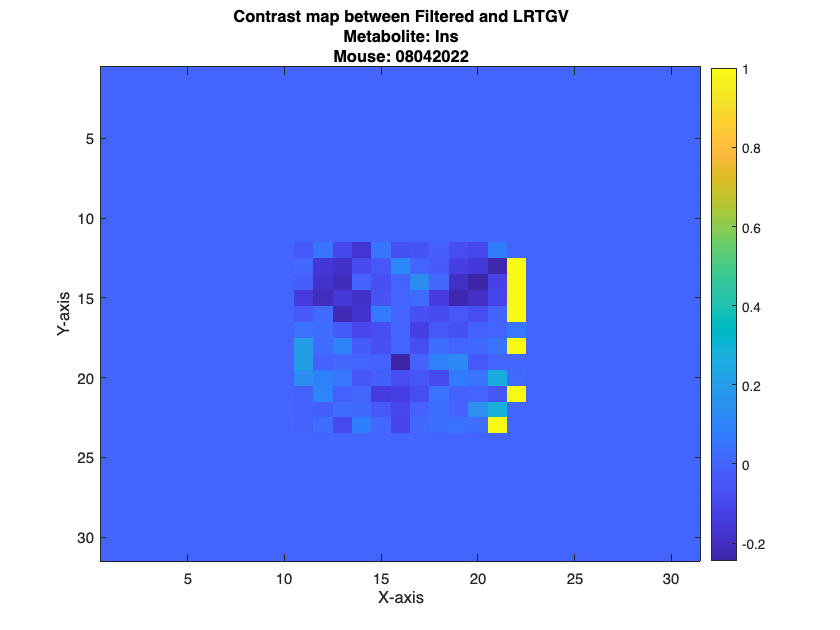


if strcmp(metab,'Ins')
    idx = ins_idx;
elseif strcmp(metab,'GABA')
    idx = gaba_idx;
else
    idx = naa_idx;
end


% MAPS 
map1 = squeeze(loaded_data(rat_nber,col_lrtgv).data.met_map.rel_conc(idx,:,:));
map2 = squeeze(loaded_data(rat_nber,col_filtered).data.met_map.rel_conc(idx,:,:));

% SNR MAPS 
SNR_map1 = loaded_data(rat_nber,col_lrtgv).data.met_map.SNR>4;
SNR_map2 = loaded_data(rat_nber,col_filtered).data.met_map.SNR>4;

% APPLYING SNR THRESHOLD
map1_th = squeeze(map1.*SNR_map1);
map2_th = squeeze(map2.*SNR_map2);

% COMPUTING DIFF STANDARDIZED
difference_map = (map1_th-map2_th)./map1_th;
difference_map(map1_th == 0) = 0;


fig = figure;

% Heat map
imagesc(difference_map);
colorbar; 
title({
    'Contrast map between Filtered and LRTGV', ...
    ['Metabolite: ' metab], ...
    ['Mouse: ' rat_dates{rat_nber}]
    });xlabel('X-axis');
ylabel('Y-axis');

Now that we have a map for a single rat on the comparison of filtered vs LRTGV, we can do the same thing for all rat and all differences (Filtered - LRTV, Filtered - MP PCA, MP PCA - LRTGV). We can then save the plots.

We will have 3 plots per metabolite per rat thus 3x3x4, 36 plots in total

% For each rat
clc;
metabs = {'Ins', 'GABA', 'NAA'};
col_mppca = 3;
col_lrtgv = 2;
col_filtered = 1;

contrasts = {
    {2, 1, 'LRTGV - Filtered'},
    {3, 1, 'MPPCA - Filtered'},
    {3, 2, 'MPPCA - LRTGV'} 
};

map_nber = 0;

base_save_path = 'MRI_Practicals/plots/contrastmaps/contrastmapabs';


METHOD = 'ABS'

METHOD = 'ABS'

METHOD = 'Normal'

METHOD = 'Normal'


if strcmp(METHOD,'ABS')
    base_save_path = 'MRI_Practicals/plots/contrastmaps/contrastmapabs';
else
    base_save_path = 'MRI_Practicals/plots/contrastmaps/contrastmapnormal';
end

disp('BEGIN');

BEGIN


MAP 0


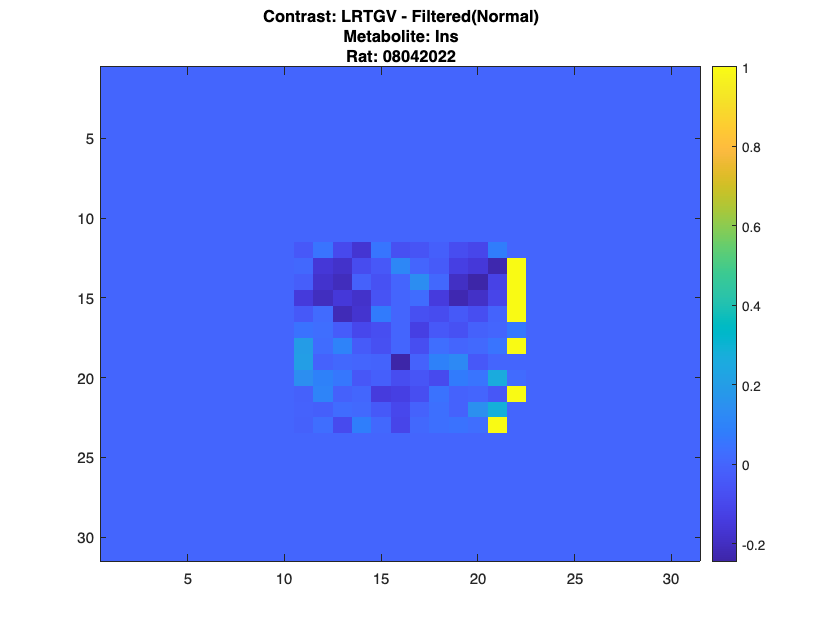

MAP 1


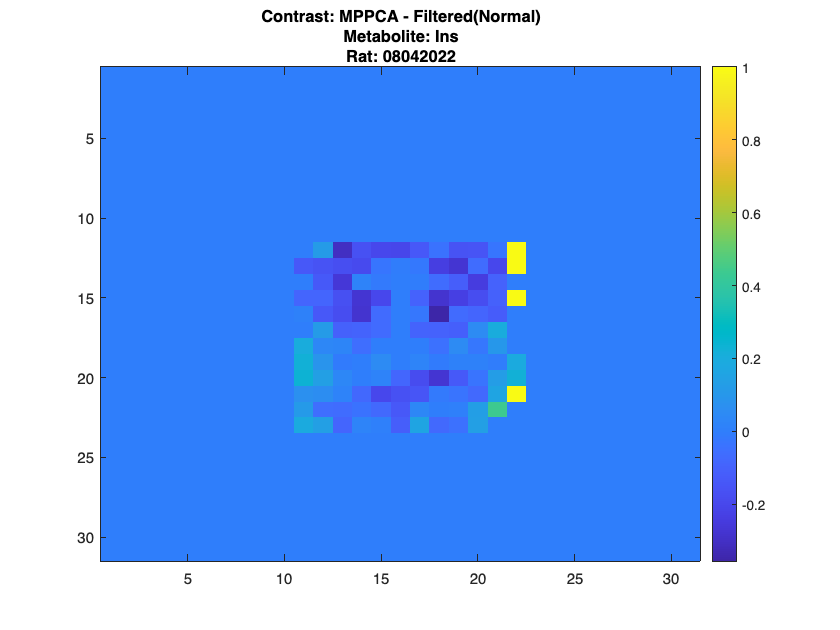

MAP 2


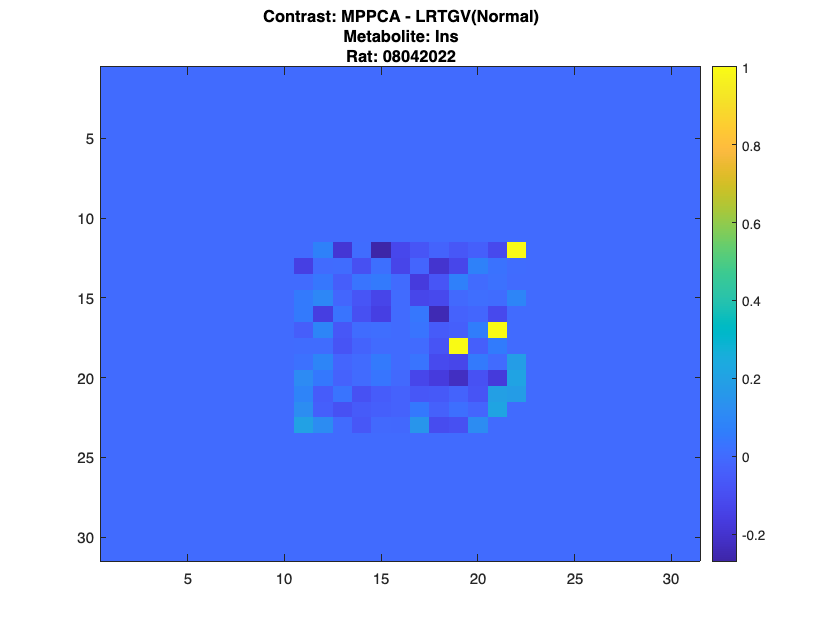

MAP 3


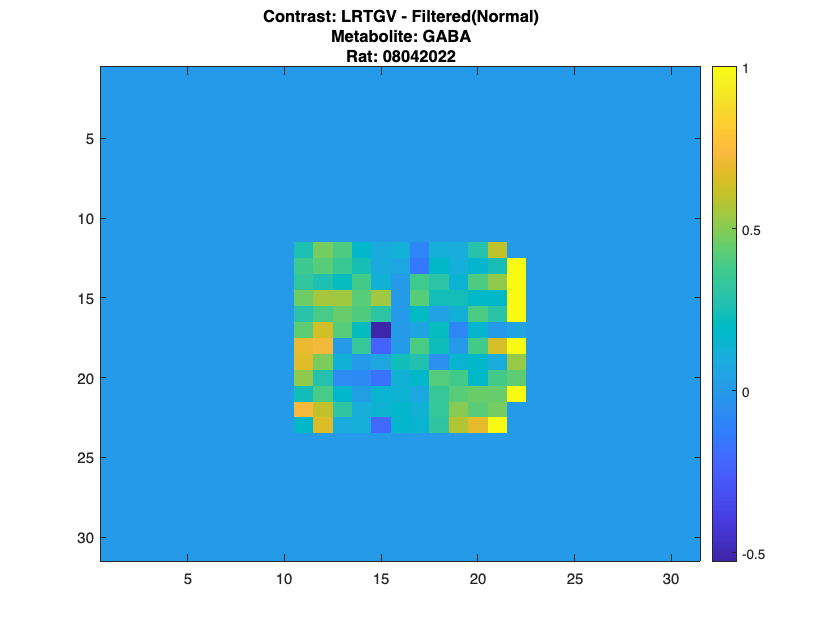

MAP 4


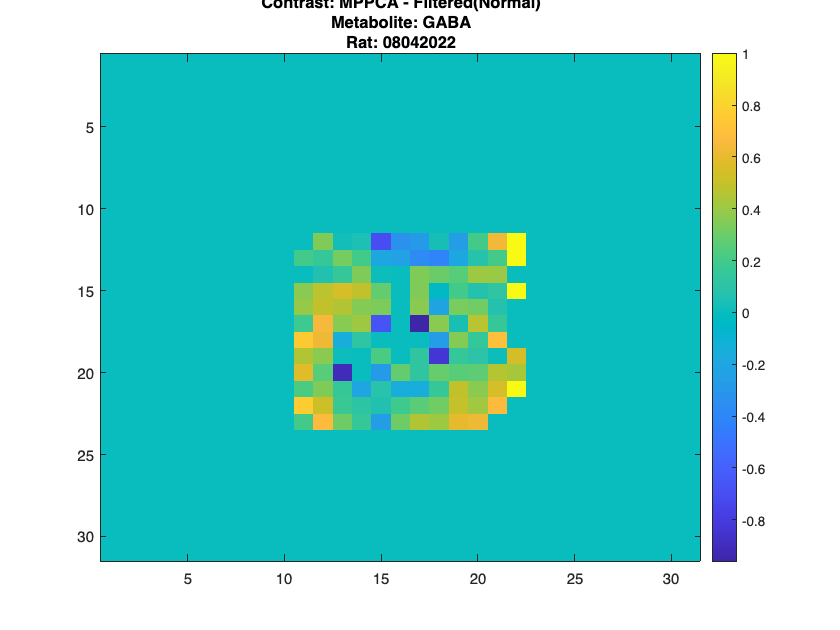

MAP 5


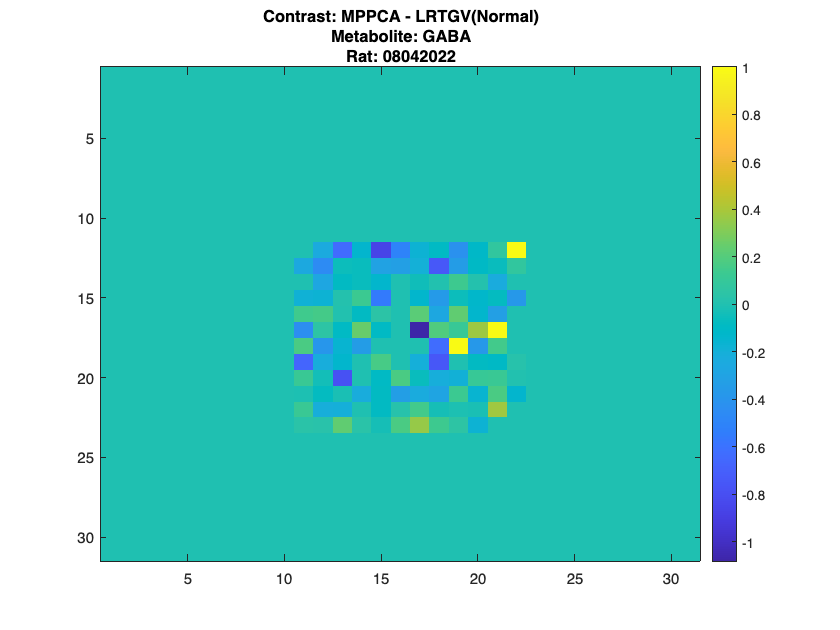

MAP 6


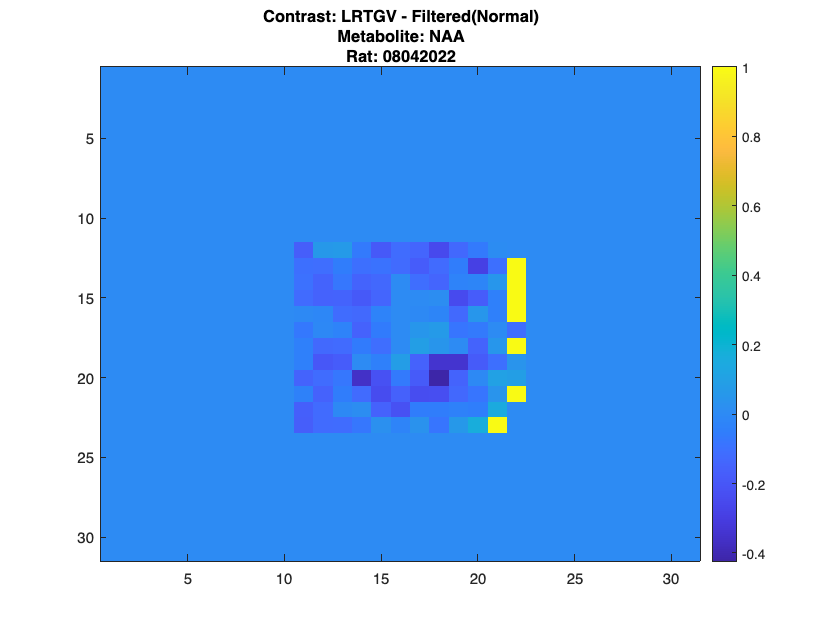

MAP 7


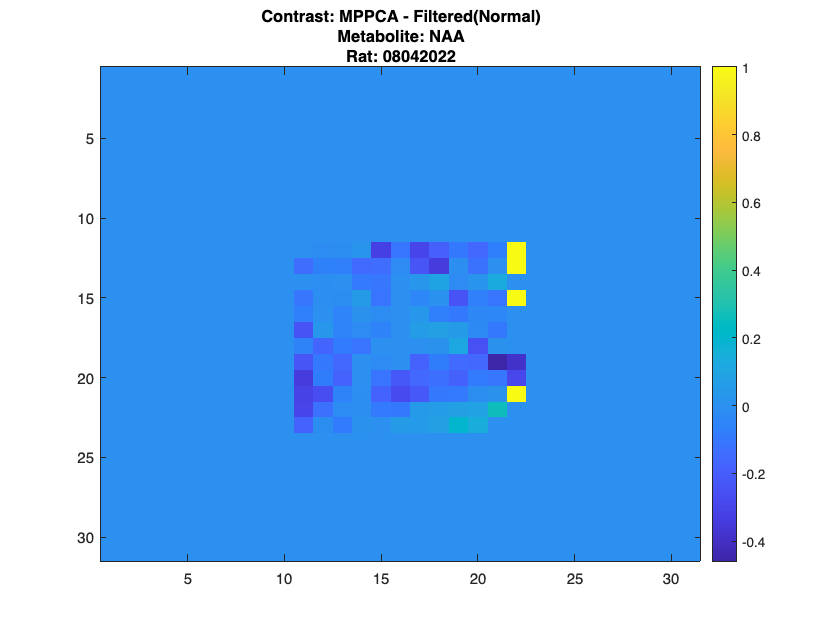

MAP 8


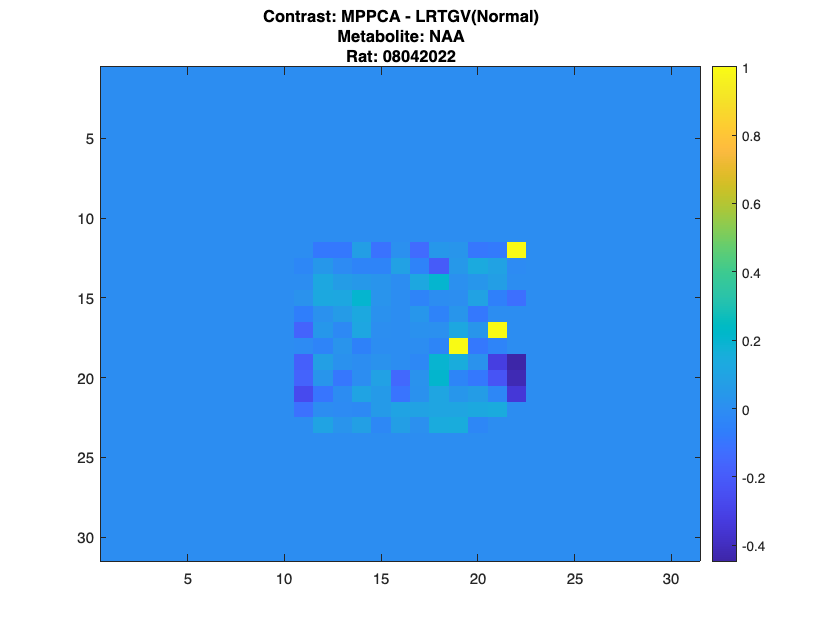

MAP 9


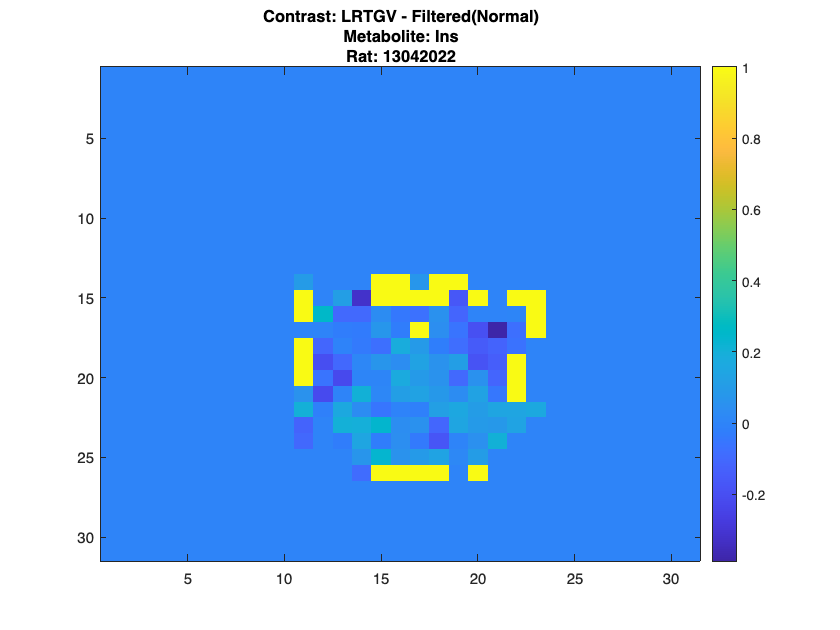

MAP 10


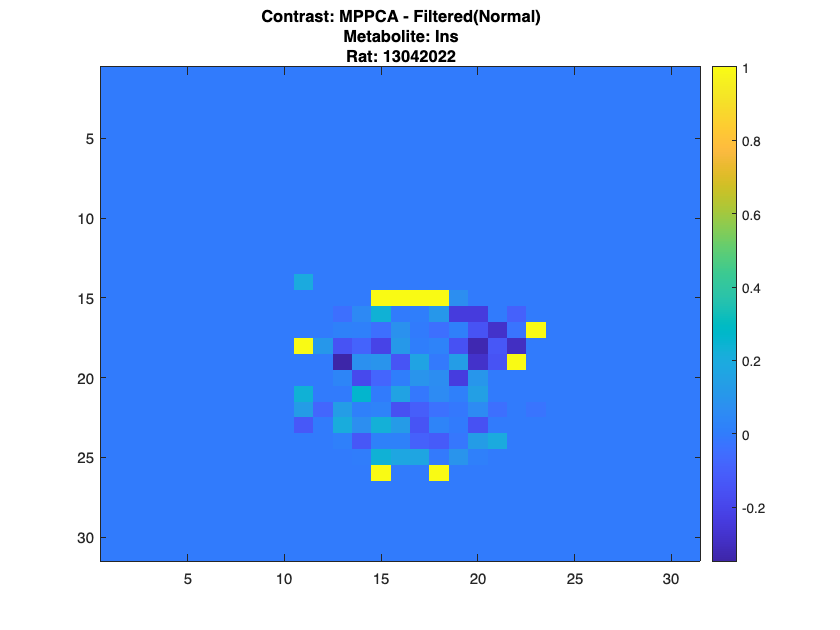

MAP 11


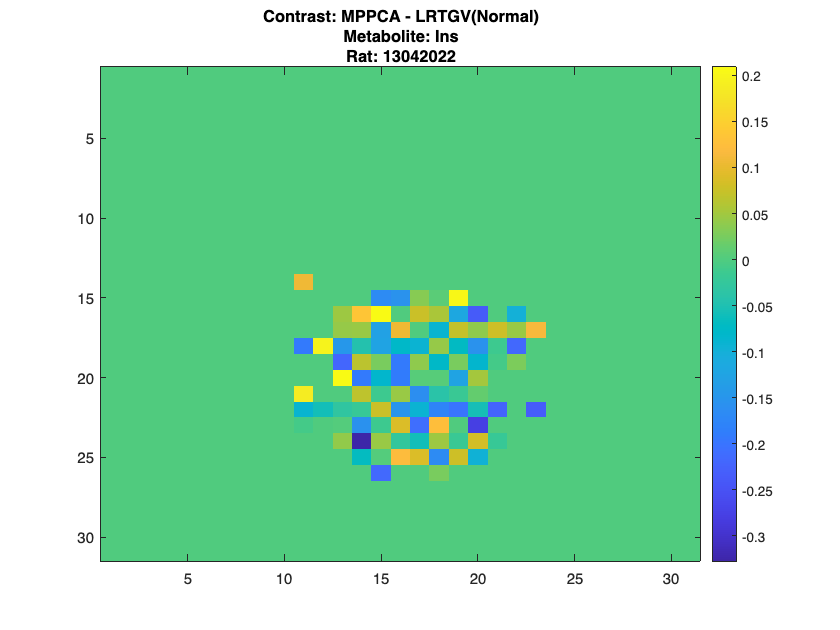

MAP 12


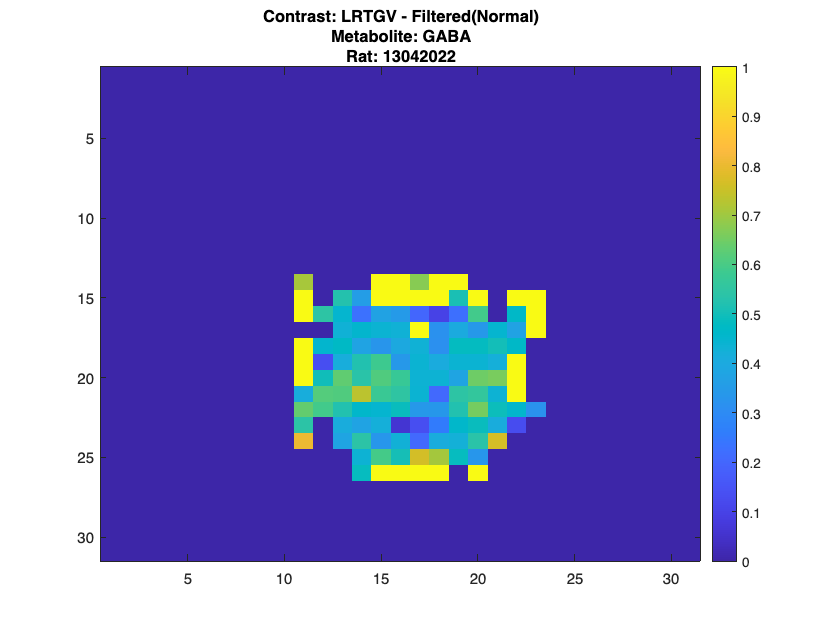

MAP 13


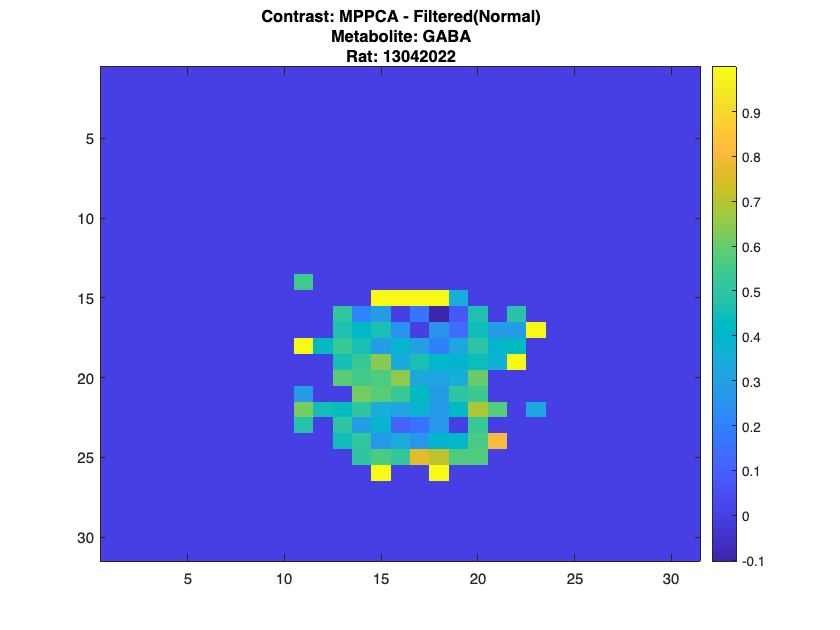

MAP 14


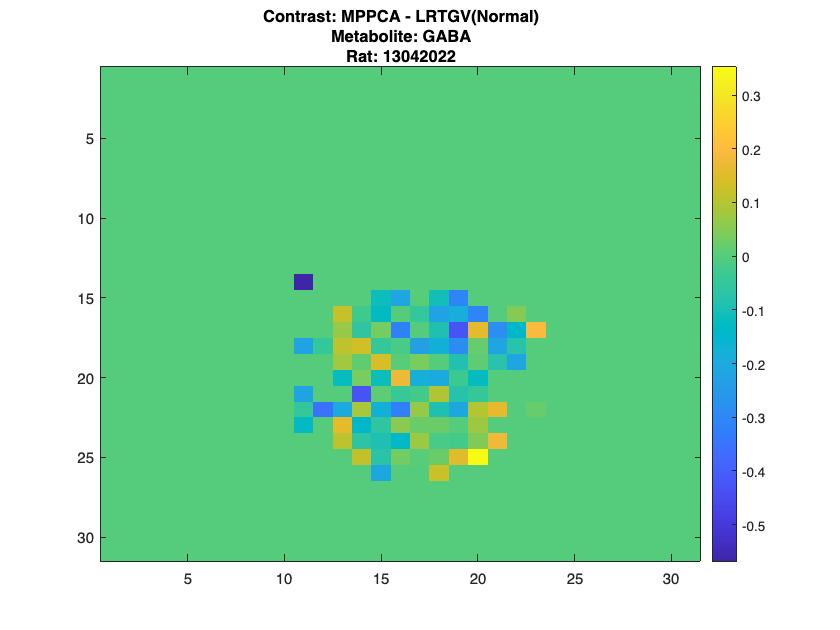

MAP 15


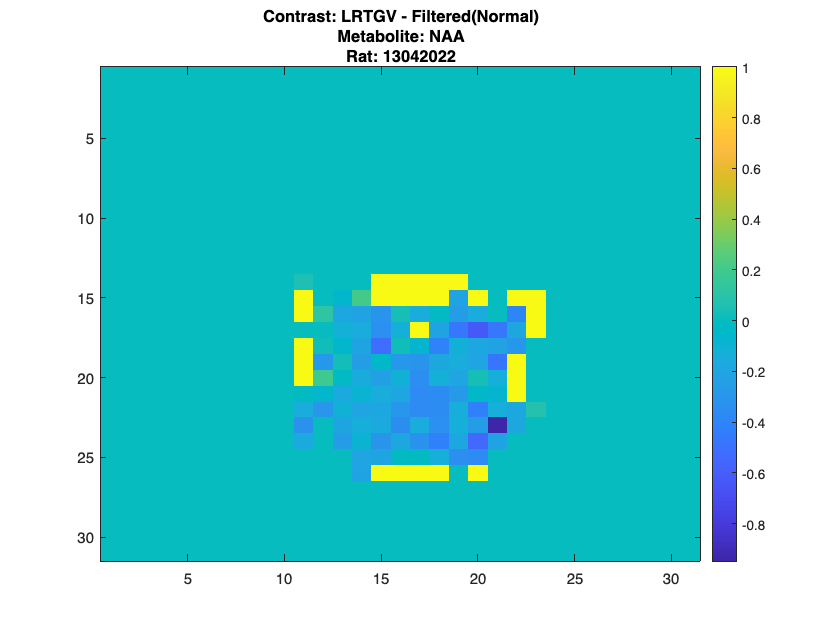

MAP 16


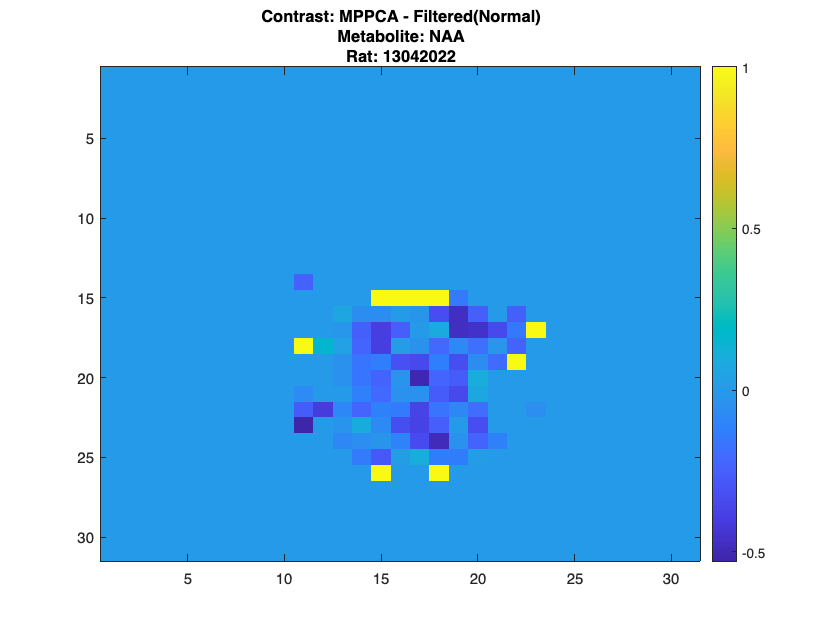

MAP 17


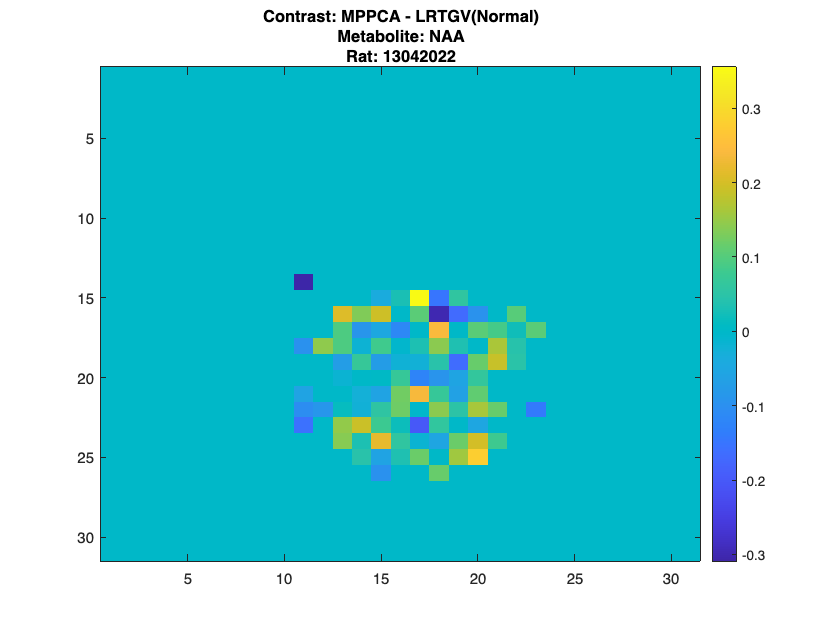

MAP 18


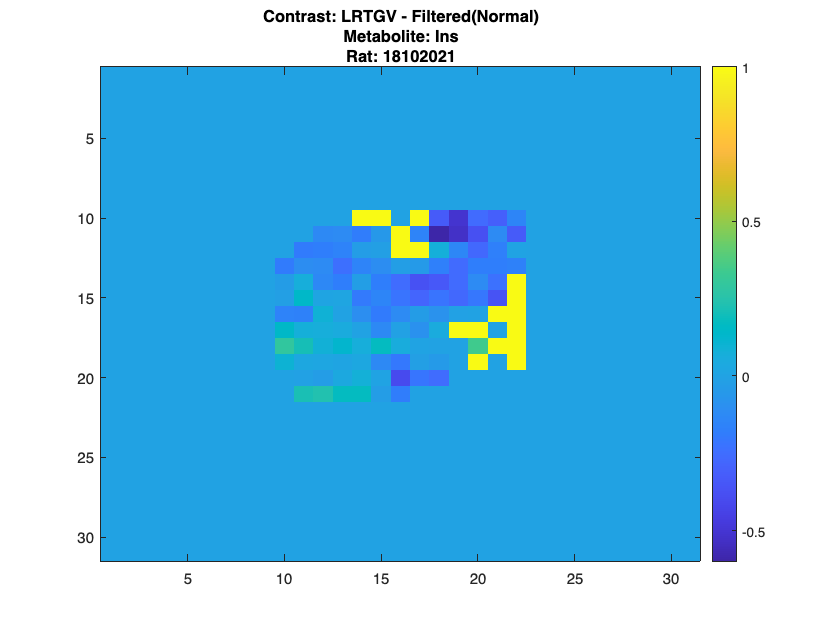

MAP 19


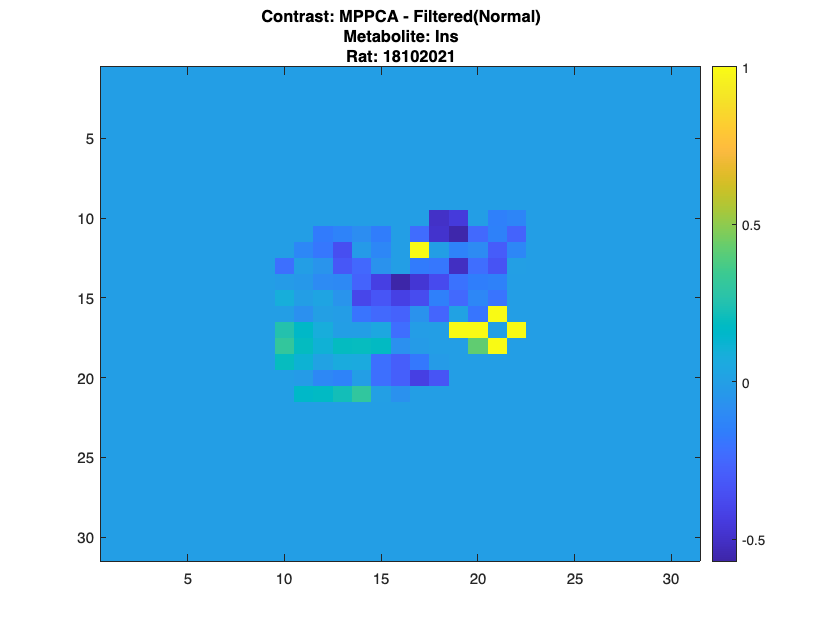

MAP 20


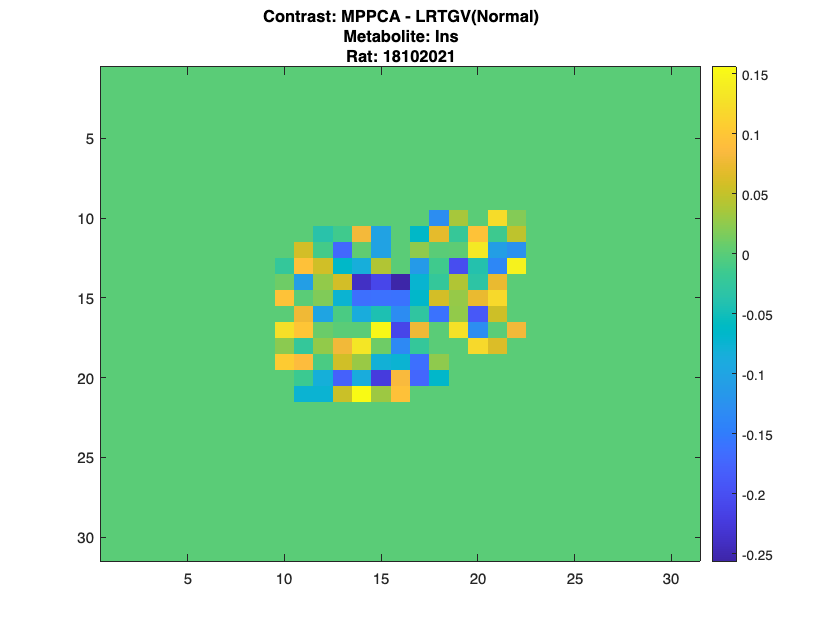

MAP 21


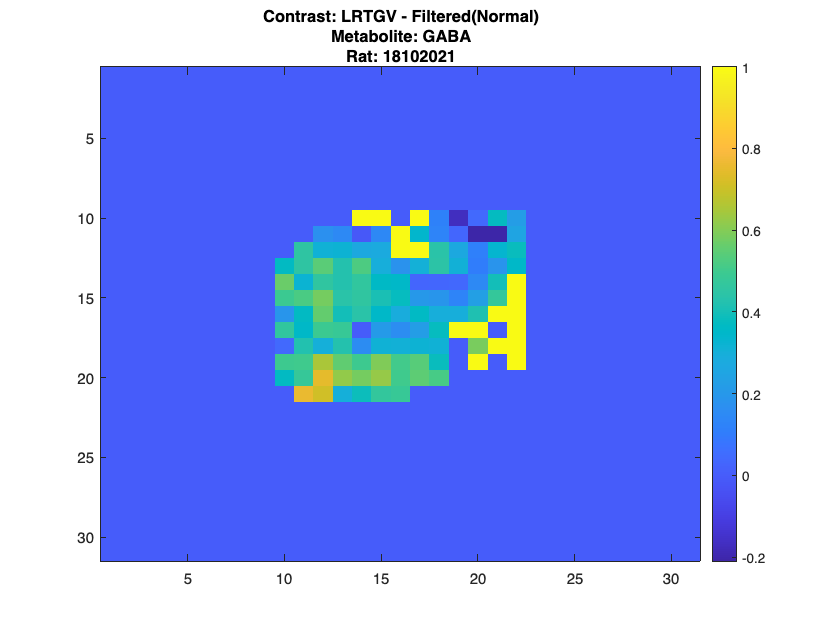

MAP 22


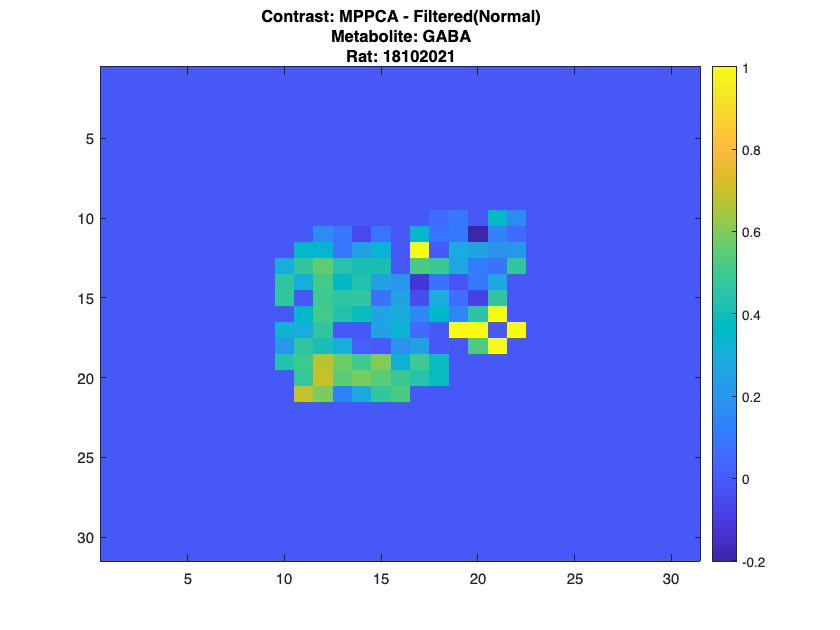

MAP 23


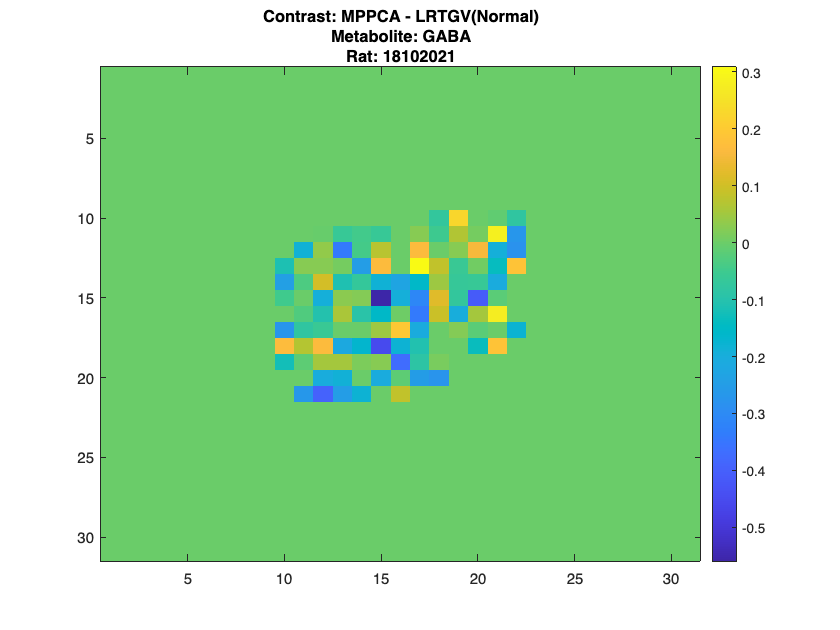

MAP 24


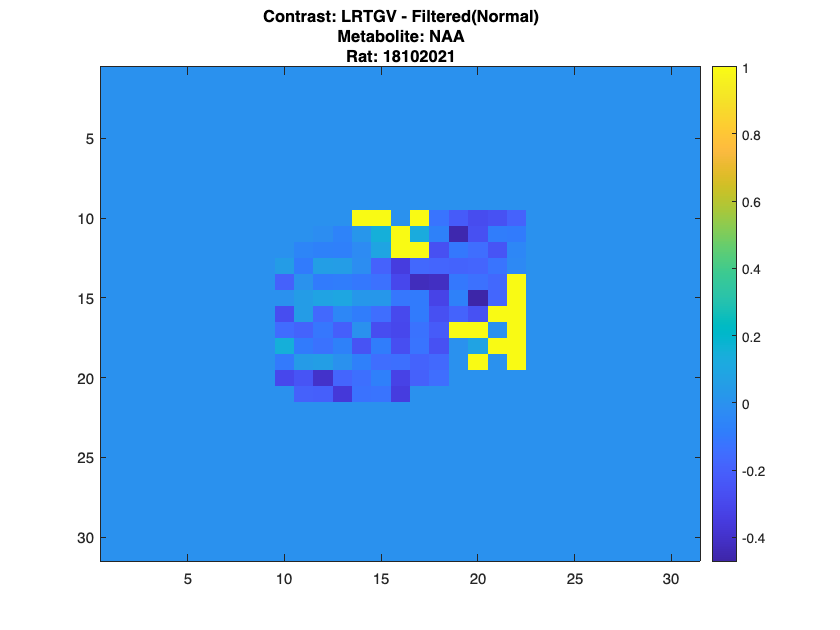

MAP 25


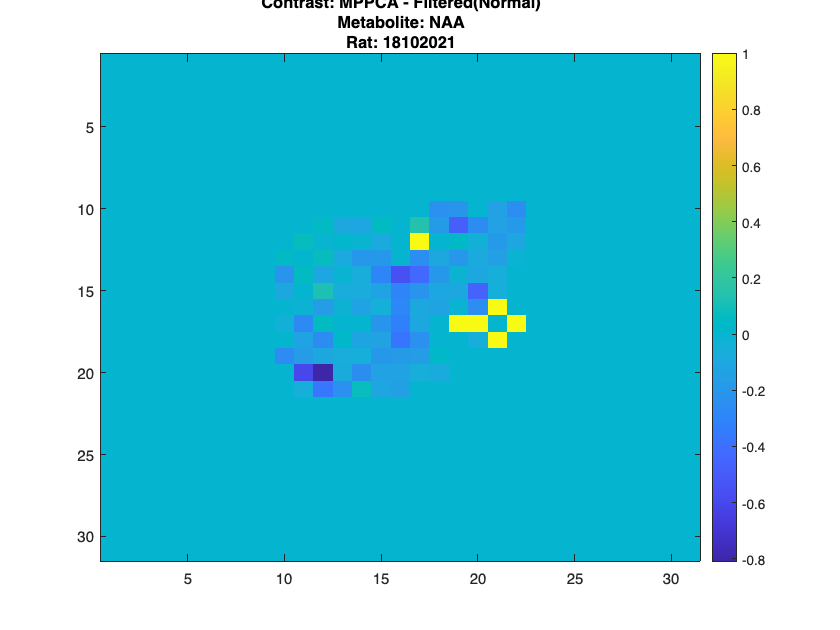

MAP 26


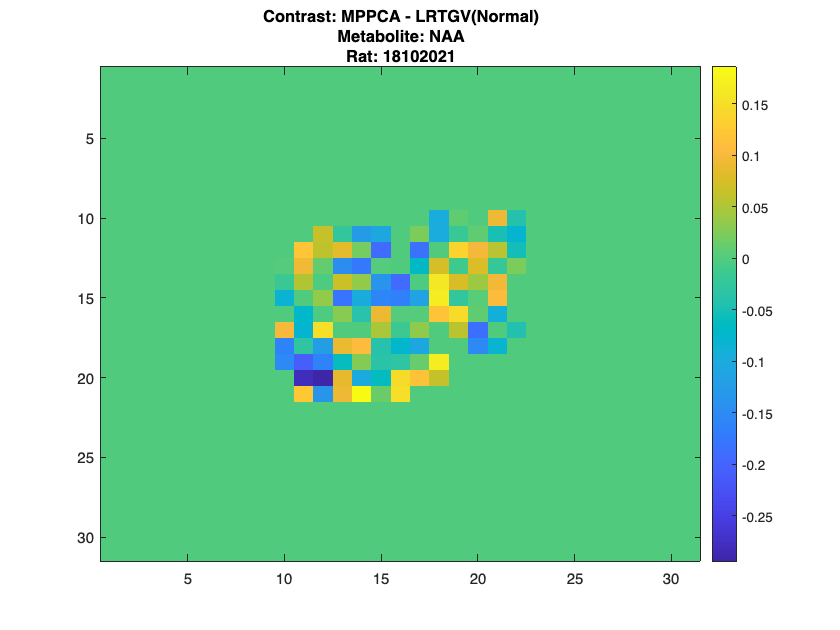

MAP 27


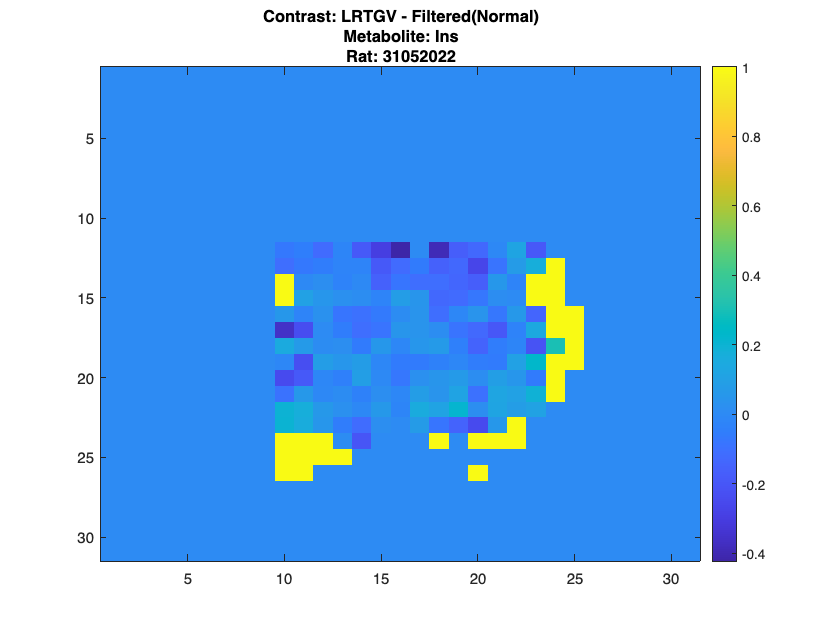

MAP 28


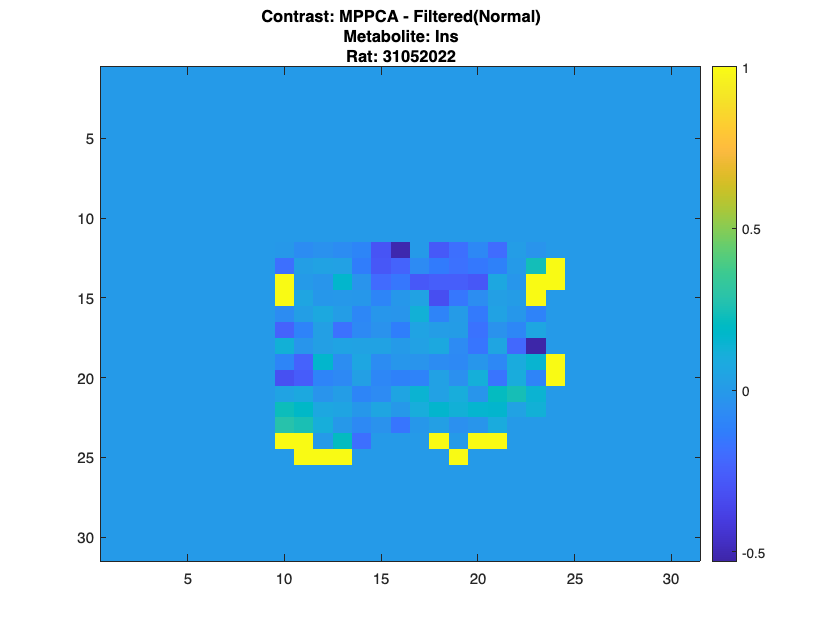

MAP 29


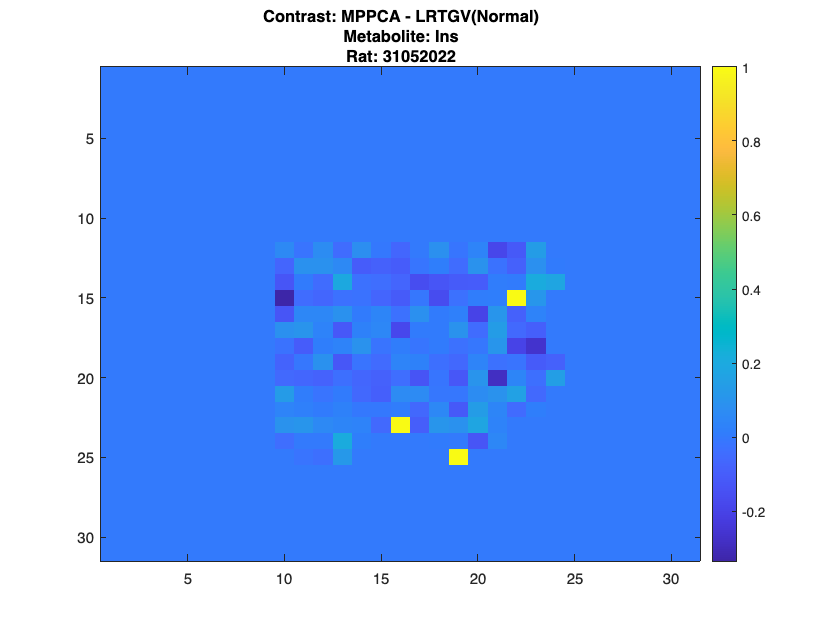

MAP 30


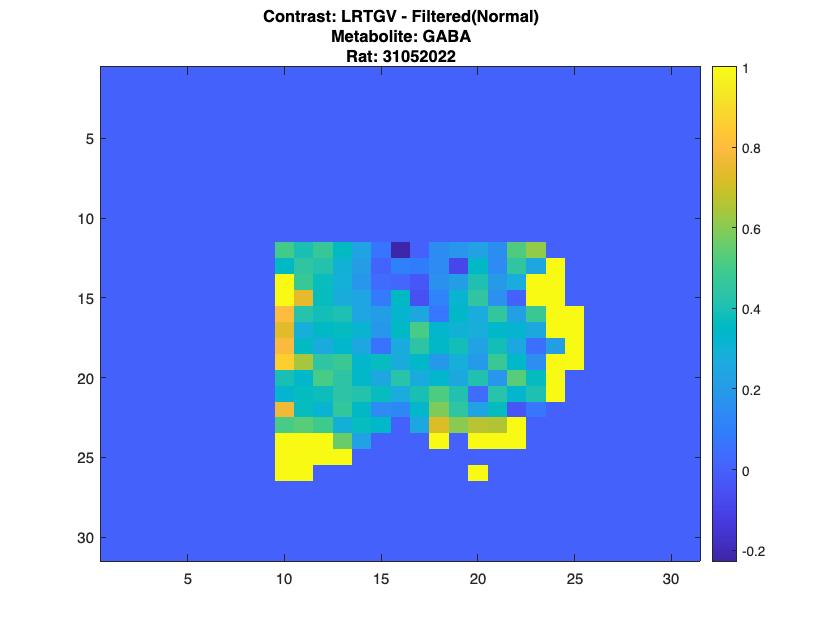

MAP 31


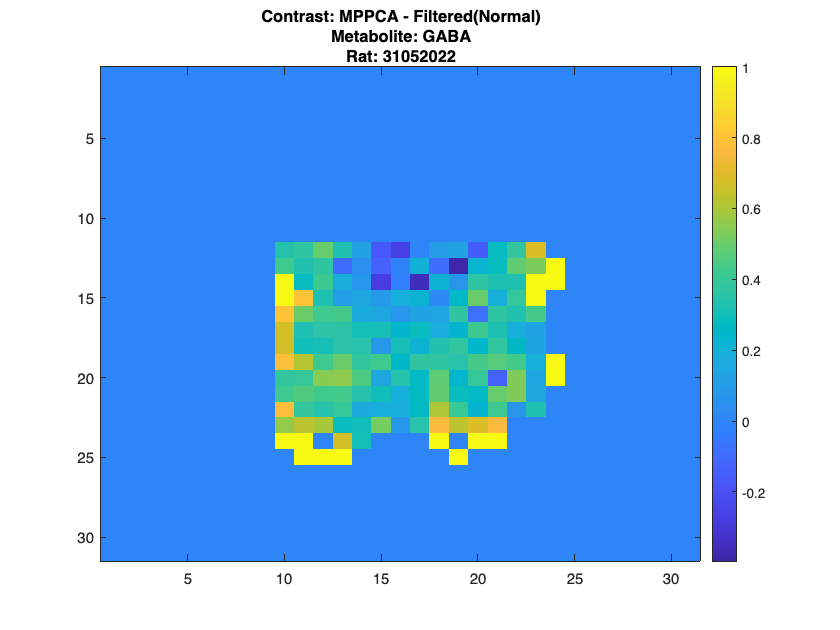

MAP 32


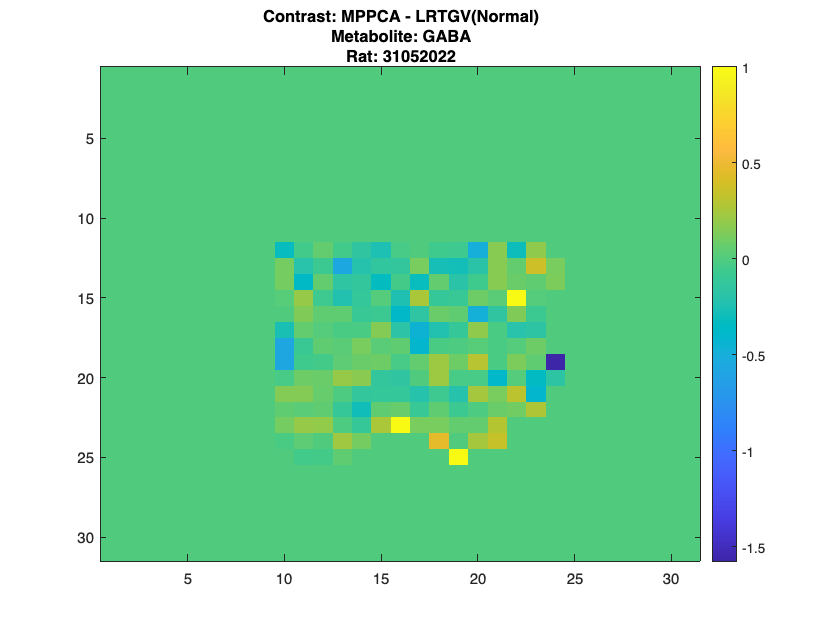

MAP 33


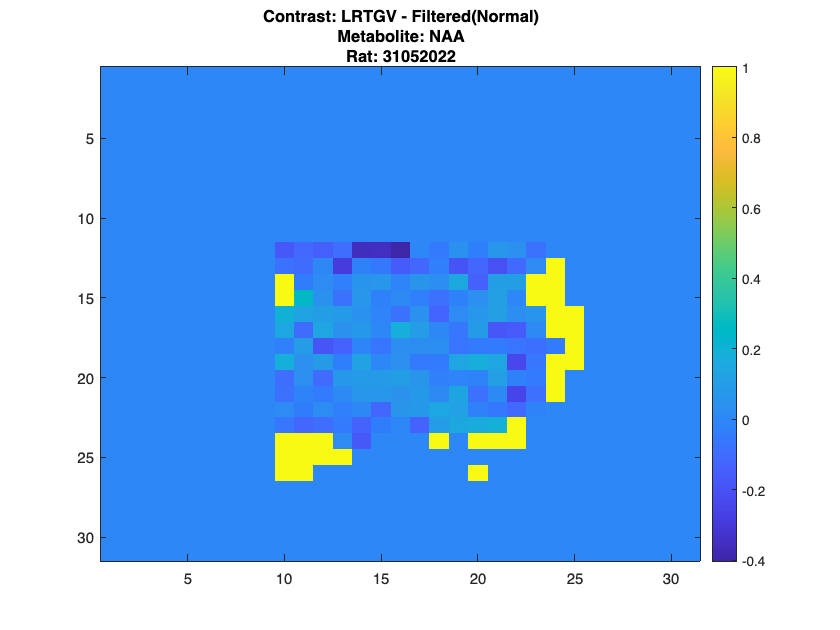

MAP 34


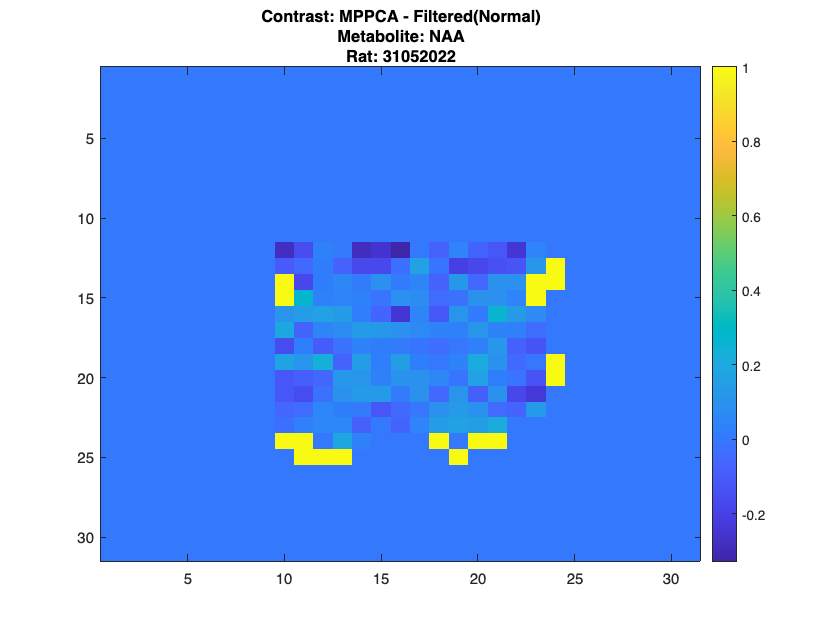

MAP 35


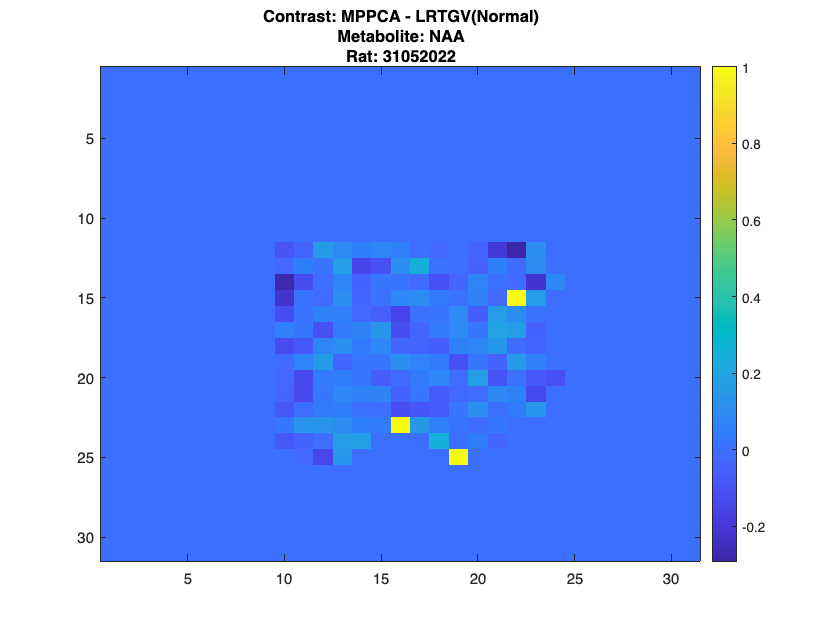

for rat_nber = 1:4
    for metab_nber = 1:3
        for contrast_nber = 1:length(contrasts)
            
            col_1 = contrasts{contrast_nber}{1};
            col_2 = contrasts{contrast_nber}{2};
            
            metab = metabs{metab_nber};
            
            if strcmp(metab, 'Ins')
                idx = ins_idx;
            elseif strcmp(metab, 'GABA')
                idx = gaba_idx;
            elseif strcmp(metab, 'NAA')
                idx = naa_idx;
            end
            
            % MAPS
            map1 = squeeze(loaded_data(rat_nber, col_1).data.met_map.rel_conc(idx, :, :));
            map2 = squeeze(loaded_data(rat_nber, col_2).data.met_map.rel_conc(idx, :, :));
            
            % SNR MAPS
            SNR_map1 = loaded_data(rat_nber, col_1).data.met_map.SNR > 4;
            SNR_map2 = loaded_data(rat_nber, col_2).data.met_map.SNR > 4;
            
            % APPLYING SNR THRESHOLD
            map1_th = squeeze(map1 .* SNR_map1);
            map2_th = squeeze(map2 .* SNR_map2);
            
            % COMPUTING DIFF STANDARDIZED
            
            if strcmp(METHOD,'ABS')
                % ABS
                difference_map = abs(map1_th - map2_th) ./ map1_th;
                difference_map(map1_th == 0) = -1;
            else
                % NORMAL
                difference_map = (map1_th - map2_th) ./ map1_th;
                difference_map(map1_th == 0) = 0;


            end

            


            
            fig = figure;
            
            % Heat map
            disp(['MAP ' num2str(map_nber)]);
            imagesc(difference_map);
            colorbar;
            title({
                ['Contrast: ' contrasts{contrast_nber}{3} '(' METHOD ')'], ...
                ['Metabolite: ' metab], ...
                ['Rat: ' rat_dates{rat_nber}]
            });

            
            % Save the figure
            save_path = fullfile(base_save_path, ['Rat' rat_dates{rat_nber} '_Metab' metab '_Contrast' contrasts{contrast_nber}{3} '.png']);
            saveas(fig, save_path);
            
            map_nber = map_nber + 1;
            
        end
    end
end

disp('HHH')

HHH



pause(2)
disp('jh')

jh
